
T = readtable("Log_ajustado.csv", ...
    "VariableNamingRule","preserve");

time = T.("Time");
rpm_in = T.("Clutch RPM in");
rpm_out = T.("Clutch RPM out");

sigma0 = 335063                    % Stiffness Ceofficient [N/m]

sigma0 = 335063

sigma1 = 0.289                     % Damping Coefficient [N.s/m]

sigma1 = 0.2890

sigma2 = 2.0                       % Viscous Friction Coefficient [N.s/m]

sigma2 = 2


r_eq_clutch = 0.10                 % Equivalent Clutch Radius [m]

r_eq_clutch = 0.1000


vs = 0.1                           % Stribeck Velocity [m/s]

vs = 0.1000


mi_s = 0.40                        % Static Friction Coefficient

mi_s = 0.4000

mi_c = 0.30                        % Dynamic Friction Coefficient

mi_c = 0.3000


N_clutch = 20000                   % Maximum Normal Clutch Force (actuator force) [N]

N_clutch = 20000


T_resistance = -10

J_rotor = 0.2000


J_load = 0.2

J_load = 0.2000

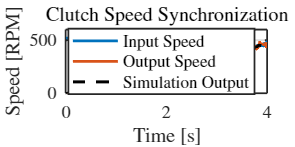


%(80ms,250ms)
if(length(out.w_out)==401)
    out.w_out(401) = [];
end

figure(1)
clf

set(gcf,'Color','w');
set(gcf,'Position',[100 100 900 450]);

plot(time, rpm_in, ...
    'LineWidth',1.8, ...
    'Color',[0 0.4470 0.7410]);
hold on

plot(time, rpm_out, ...
    'LineWidth',1.8, ...
    'Color',[0.8500 0.3250 0.0980]);

plot(time, out.w_out, ...
    '--', ...
    'LineWidth',2, ...
    'Color',[0 0 0]);

grid on
box on

xlabel('Time [s]','Interpreter','latex','FontSize',13)
ylabel('Speed [RPM]','Interpreter','latex','FontSize',13)

title('Clutch Speed Synchronization','Interpreter','latex','FontSize',15)

legend({'Input Speed','Output Speed','Simulation Output'}, ...
    'Location','best', ...
    'Interpreter','latex', ...
    'FontSize',11)

xlim([0 4])
ylim([0 600])

set(gca,...
    'FontSize',12,...
    'LineWidth',1.2,...
    'TickLabelInterpreter','latex');